n = 100;m = 1000;
[w,t]=wiener(n,m);
w=stint(w,w);

Az a-nál lesz levágva a folyamat

a=0.9

a = 0.9000

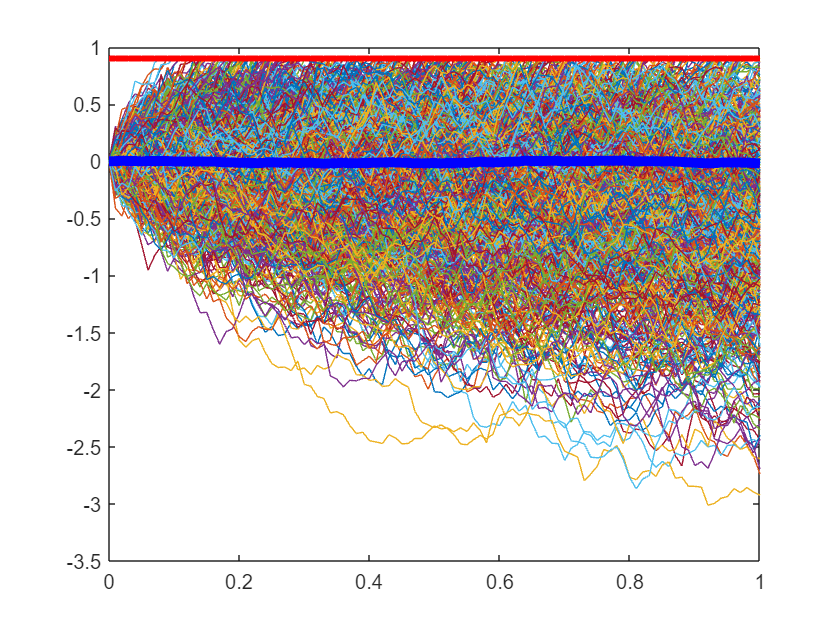

D = cumsum(w>=a);
stw = (D == 0).*w+(D>0)*a;
plot(t,stw)
hold on;
plot(t,ones(size(t))*a,'r','LineWidth',3);
plot(t,zeros(size(t)),'g','LineWidth',3);
plot(t,mean(stw,2),'b','LineWidth',5);
hold off;